disp('linear regression for straight line model ');

linear regression for straight line model 


%straight line model
% y= ax + b
x = [10 20 30 40 50 60 70 80] ; 
y = [25 70 380 550 610 1220 830 1450];

% ∑ y = a ∑ x + n b
% ∑ yx = a ∑ x^2 + b ∑ x

% get variable values

n=length(x)     ; % n  
sx = sum(x)     ; % ∑ x
sy = sum(y)     ; % ∑ y
sxy = sum(x.*y) ; % ∑ yx
sx2 = sum(x.^2) ; % ∑ x^2

% ∑ Y = a ∑ x + n B
% ∑ Yx = a ∑ x^2 + B ∑ x

% we split this two equation into two matrices

Rightcoef = [sx n  ; sx2 sx ] ;  
Leftcoef = [sy ; sxy] ; 
%solve as matrices
%think of it as 
%Leftcoef = Rightcoef  * sol
sol = Rightcoef \ Leftcoef  ; % as same as 'sol  = Rightcoef^-1 * Leftcoef' but the backslash expression is more effcint for more info : https://www.mathworks.com/help/matlab/ref/mldivide.html

a = sol(1) ; %a
b = sol(2) ; %b

%calc R^2
yav = mean(y) ;
st = sum( (y-yav).^2 )  ;
sr = sum((y-b-a*x).^2) ;
r2=(st-sr)/st ;


disp('a ');disp(a) ;

a 
   19.4702



disp('b ');disp(b) ;

b 
 -234.2857



disp('r^2 ');disp(r2) ;

r^2 
    0.8805



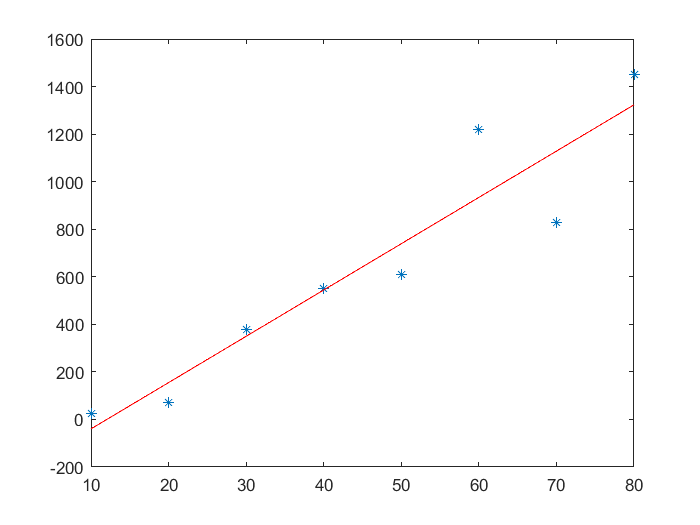


x1 = min(x):0.1:max(x); 
%y=ax+b
y1 = a*x1+b ;

plot(x,y ,'*' , x1 ,y1 ,'r-')